Xtrain = 6.*rand(100, 3) - 3;
Ytrain = sinc(Xtrain(:,1)) + 0.1.*randn(100,1);


sig2 = 0.4;
gam = 10;
crit_L1 = bay_lssvm ({ Xtrain , Ytrain , 'f', gam , sig2 }, 1);
crit_L2 = bay_lssvm ({ Xtrain , Ytrain , 'f', gam , sig2 }, 2);
crit_L3 = bay_lssvm ({ Xtrain , Ytrain , 'f', gam , sig2 }, 3);

 

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



[~,alpha,b] = bay_optimize({Xtrain, Ytrain, 'f' , gam, sig2}, 1);

A =     0.9183
    2.1046
   -0.7094
   -1.4602
    0.3035
   -0.9041
   -0.7872
   -0.2256
    0.8733
    0.7002


[~,gam] = bay_optimize({Xtrain, Ytrain, 'f' , gam, sig2}, 2);

 

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


[~,sig2] = bay_optimize({Xtrain, Ytrain, 'f' , gam, sig2}, 3);

 
 

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>
 

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<





[selected, ranking] = bay_lssvmARD({Xtrain, Ytrain, 'f', gam, sig2});

ans = 'OPTIMIZING GAMMA AND KERNEL PARAMETERS WITH BAYESIAN FRAMEWORK OVER ALL INPUTS...'

 
 

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>
 

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

ans = 'testing for 3 inputs'

 

Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>
 

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping c

ans = 'SELECTED INPUT(S) ('discrete'): [1  3]'

ans = 'testing for 2 inputs'

 

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>
 

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


ans = 'SELECTED INPUT(S) ('discrete'): [1]'

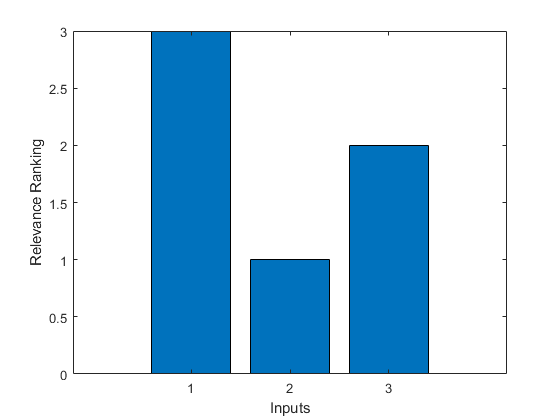

% visualize the ranking of the relevant inputs

rankscore = [3;2;1];

bar(ranking,rankscore)
xlabel('Inputs') 
ylabel('Relevance Ranking') 